rng(22)

Average_reward = zeros(6,test_round);

Reward_all(6,:) = zeros(1,test_round);

for j = 1:test_round
    Reward_all(6,j) = Reward_all(5,j) + (rand)*(Reward_all(5,j) - Reward_all(2,j));
end
Reward_all;

for i = 1:6
    Average_reward(i,1) = Reward_all(i,1);
    for j = 2:test_round
        Average_reward(i,j) = Average_reward(i,j-1)*(j-1)/j + Reward_all(i,j)/j;
    end
end


Average_reward3 = zeros(6,test_round)

Average_reward3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0 

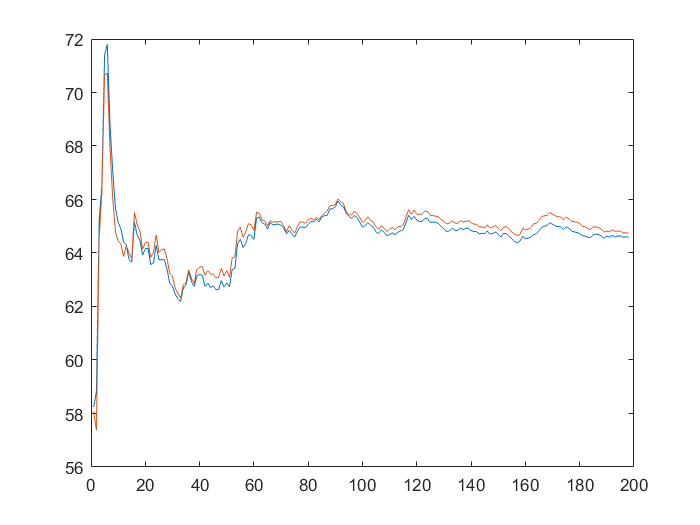


for j = 2:test_round
    for i = 1:6
        if i == 2 || i== 5
        Average_reward3(i,j) = Average_reward(i,j) - Average_reward(1,j);
        end
    end
    Average_reward3(2,j) = Average_reward3(2,j) /2;
end

%%%%%%%%% figure plot
for i = 1:6
    if i == 2 || i== 5
        plot(Average_reward(i,2:end-1))
        hold on
    end
end
hold off

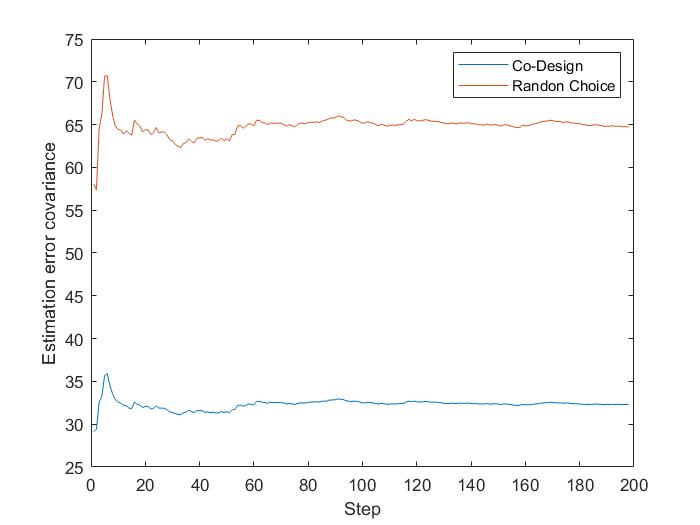


%legend("test1: rand","test2: robin-rand","test3: greedy","test4: epsilon-greedy","test5: Q-learning","test6: DQN")

for i = 1:6
    if i == 2 || i== 5
    plot(Average_reward3(i,2:end-1))
    hold on
    end
end
hold off
xlabel("Step")
ylabel("Estimation error covariance")
legend("Co-Design","Randon Choice")




P_record = P_record / T

P_record = 	1.0e+-15 *

         0    0.4901         0         0    0.3256         0
